# nGaussian Elimination with Backward Substitution

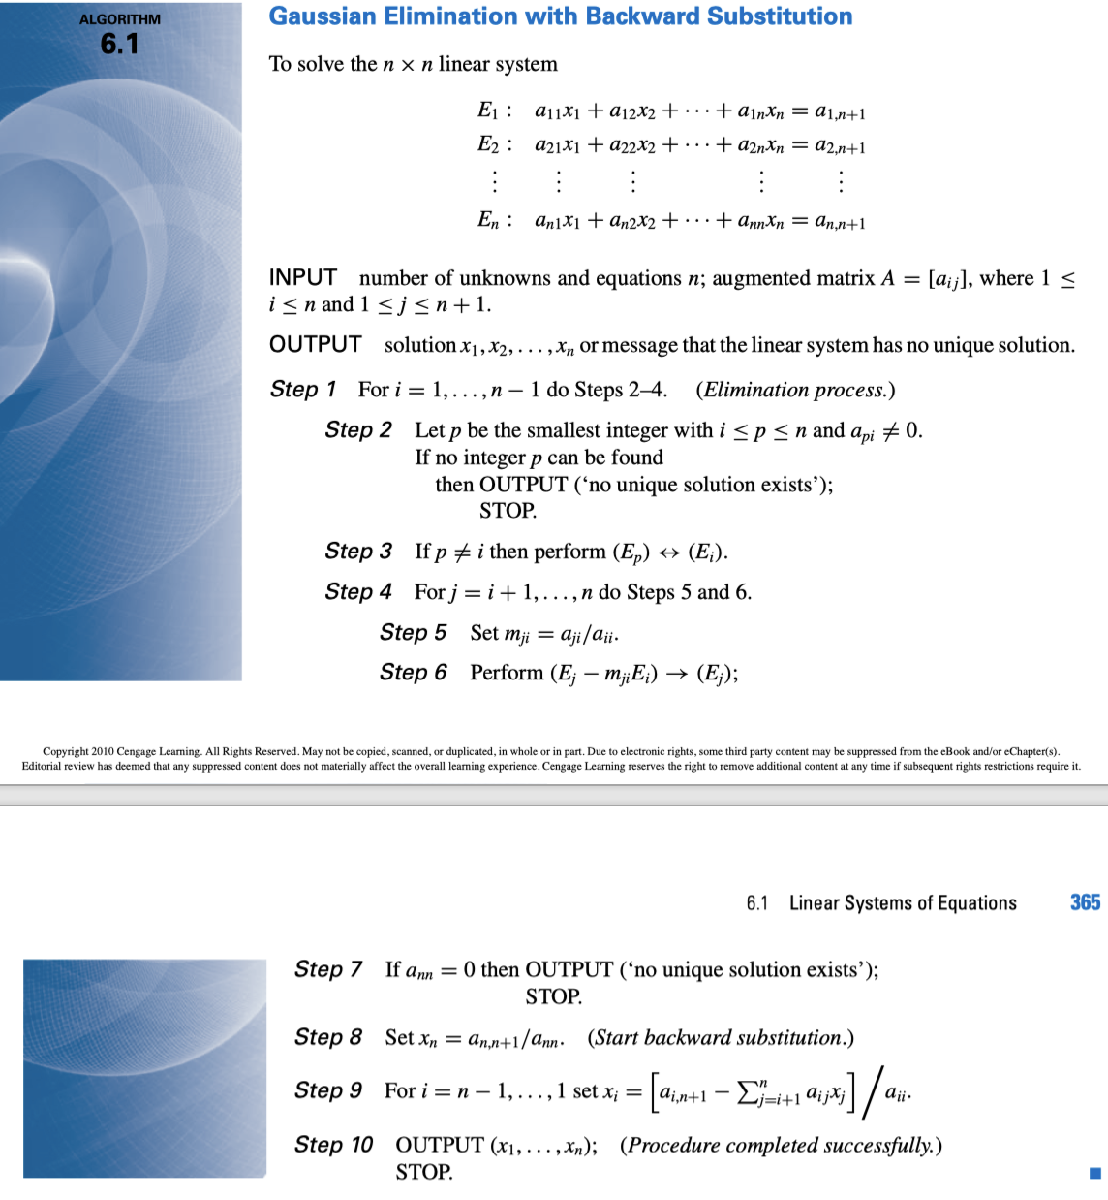

clc;clear;close all;

A=[0,0,-1,1;
    0,1,-1,2;
    0,-1,2,0;
    0,2,0,2];


rowchange=[];

Ag={};                                                  %Create a cell array to store each matrix
Aau=[A];                                              %Generate the augmented matrix
Ag{1}=Aau;                                              %Store the first initial matrix
[n,b]=size(A);
m=[];
for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    while Aau(p,i)==0 & p <= n-1    
        p=p+1;
    end
    if p==n & Aau(p,i)==0
        disp("No unique solution found, please check");
        break
    end

    %record the row exchange
    rowchange=[rowchange;i,p];
    Atemp=Aau(i,:);
    Aau(i,:)=Aau(p,:);
    Aau(p,:)=Atemp;
    for j=i+1:n
        m(j,i)=Aau(j,i)/Aau(i,i);
        Aau(j,:)=Aau(j,:)-m(j,i).*Aau(i,:);
    end
    Ag{i +1}=Aau;
end

No unique solution found, please check



P=eye(n);
[r,c]=size(rowchange);
for i=1:r
    Ptemp=P(rowchange(i,1),:);
    P(rowchange(i,1),:)=P(rowchange(i,2),:);
    P(rowchange(i,2),:)=Ptemp;
end


A=P*A;

Ag={};                                                  %Create a cell array to store each matrix
Aau=[A];                                              %Generate the augmented matrix
Ag{1}=Aau;                                              %Store the first initial matrix
[n,b]=size(A);
m=[];
for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    while Aau(p,i)==0 & p <= n-1    
        p=p+1;
    end
    if p==n & Aau(p,i)==0
        disp("No unique solution found, please check");
        break
    end

    %record the row exchange
    rowchange=[rowchange;i,p];
    Atemp=Aau(i,:);
    Aau(i,:)=Aau(p,:);
    Aau(p,:)=Atemp;
    for j=i+1:n
        m(j,i)=Aau(j,i)/Aau(i,i);
        Aau(j,:)=Aau(j,:)-m(j,i).*Aau(i,:);
    end
    Ag{i +1}=Aau;
end

No unique solution found, please check





L2=eye(n);
L1=zeros(4,4);
L1(2:n,1:n-1)=m(2:end,:);

无法执行赋值，因为左侧的大小为 3×3，右侧的大小为 0×0。

L=L1+L2;
disp(L);
U=Aau(:,1:n);






% L =
% 
%      1     0     0     0
%      1     1     0     0
%     -1     0     1     0
%      0     0    -1     1
% 
% 
% U =
% 
%      1     1    -1     2
%      0     1     1     0
%      0     0     1     2
%      0     0     0     3
% 
% 
% P =
% 
%      0     1     0     0
%      0     0     0     1
%      0     0     1     0
%      1     0     0     0